eeg3_tr=rest_state_trial.eeg1;
emg3_tr=rest_state_trial.eeg7;
eeg3_tr=eeg3_tr*(3.3/4096);
emg3_tr=emg3_tr*(3.3/4096);
f_data3=length(emg3_tr)/120;
t_data3=1/f_data3;
Time_d3=[0:1:length(eeg3_tr)-1]*t_data3;

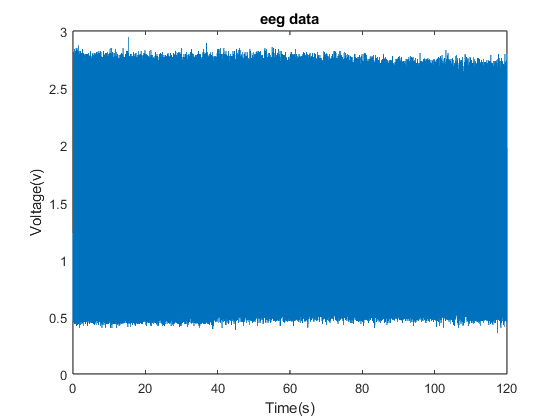

plot(Time_d3,eeg3_tr)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')

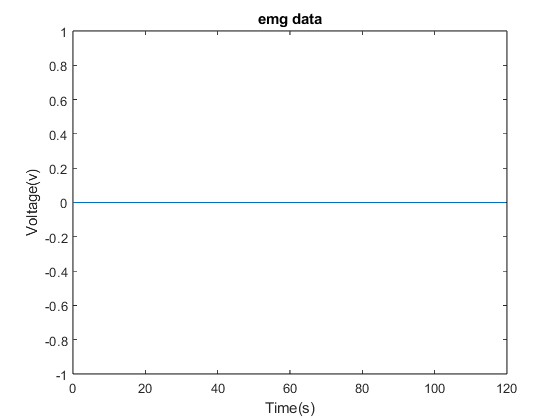

plot(Time_d3,emg3_tr)
title('emg data')
xlabel('Time(s)')
ylabel('Voltage(v)')

eeg2_tr_fft=fft(eeg3_tr);
eeg2_tr_fft(1)=0;
eeg3_tr=ifft(eeg2_tr_fft);

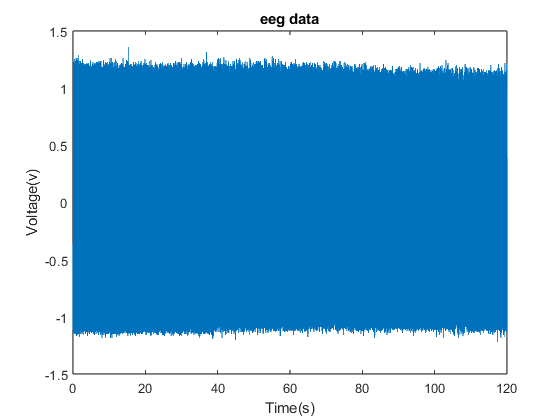

plot(Time_d3,eeg3_tr)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')

emg2_tr_fft=fft(emg3_tr);
emg2_tr_fft(1)=0;
emg3_tr=ifft(emg2_tr_fft);

plot(Time_d3,emg3_tr)
title('emg data')
xlabel('Time(s)')
ylabel('Voltage(v)')

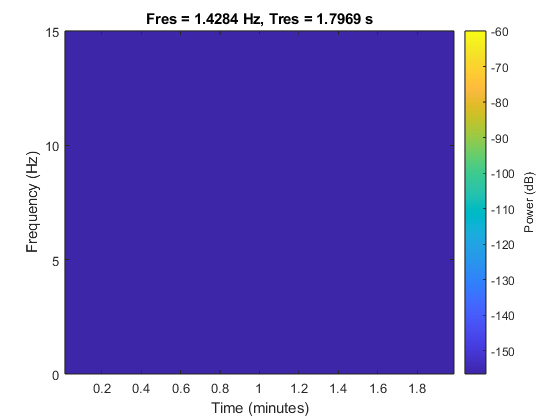

pspectrum(emg3_tr,f_data3,"spectrogram","FrequencyLimits",[0,15],"MinThreshold",-60,"OverlapPercent",90,"TimeResolution",1.8);

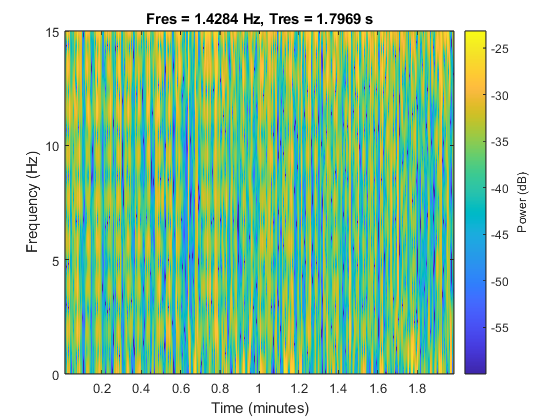

pspectrum(eeg3_tr,f_data3,"spectrogram","FrequencyLimits",[0,15],"MinThreshold",-60,"OverlapPercent",90,"TimeResolution",1.8);

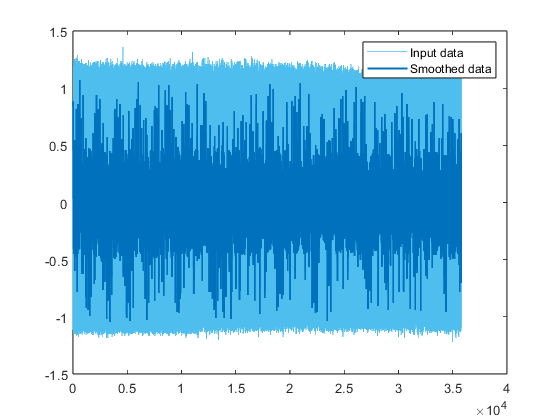

% Smooth input data
eeg3_smooth = smoothdata(eeg3_tr,"movmedian",7);

% Display results
clf
plot(eeg3_tr,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(eeg3_smooth,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

% Smooth input data
eeg_smooth2 = smoothdata(eeg2_tr,"movmean",[4 1]);

Unrecognized function or variable 'eeg2_tr'.


% Display results
clf
plot(eeg2_tr,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(eeg_smooth2,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend


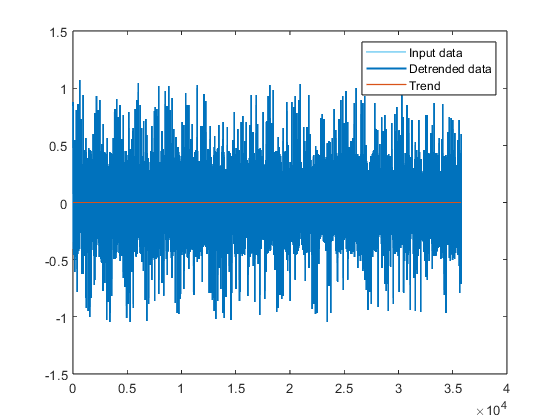

% Remove trend from data
eeg3_smooth = detrend(eeg3_smooth);

% Display results
clf
plot(eeg3_smooth,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(eeg3_smooth,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Detrended data")
plot(eeg3_smooth-eeg3_smooth,"Color",[217 83 25]/255,"LineWidth",1,...
    "DisplayName","Trend")
hold off
legend

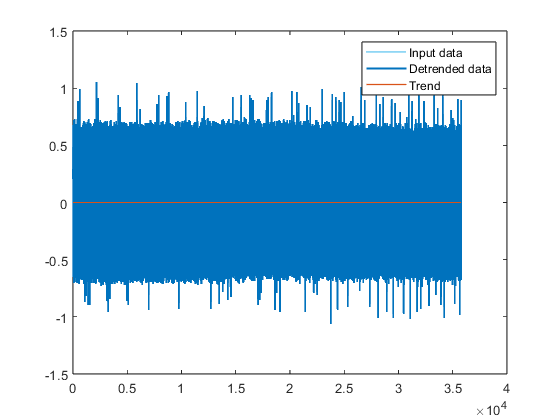

% Remove trend from data
emg_smooth2 = detrend(emg_smooth2);

% Display results
clf
plot(emg_smooth2,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(emg_smooth2,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Detrended data")
plot(emg_smooth2-emg_smooth2,"Color",[217 83 25]/255,"LineWidth",1,...
    "DisplayName","Trend")
hold off
legend

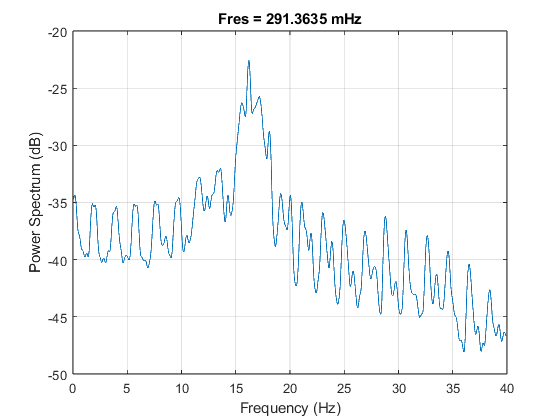

pspectrum(eeg3_smooth,f_data3,"power","FrequencyLimits",[0,40])%"FrequencyLimits",[0,15],"MinThreshold",-40,"OverlapPercent",90,"TimeResolution",1);

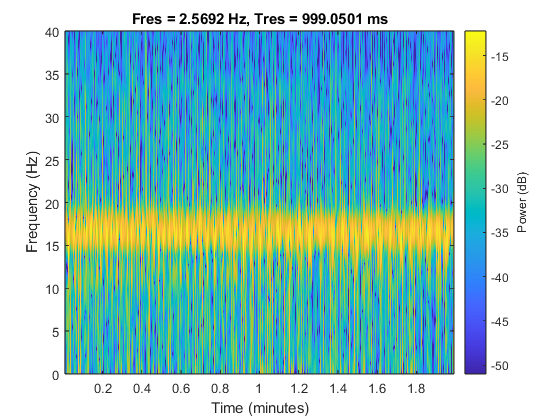

pspectrum(eeg3_smooth,f_data3,"spectrogram","FrequencyLimits",[0,40],"MinThreshold",-51,"OverlapPercent",99,"TimeResolution",1);


writematrix(eeg3_tr,'D:\matlab\ymaps_code\data\rest_state_.csv');
writematrix(eeg3_smooth,'D:\matlab\ymaps_code\data\rest_state_smooth.csv');